clc, clear, format longG, close all

% C = load('C.txt');
% for i = 1:16
%     subplot(4, 4, i)
% %     bar(C(i, :))
% plot(C(i, :))
%     tick = {'SSA-VAL' 'VSSA-VAL' 'REAL-VAL' 'SSA-VAR' 'VSSA-VAR' 'SSA-ITE' 'VSSA-ITE'};
%     % settick('re_shu',tick);
%     % 设置横坐标
%     set(gca, 'XTickLabel', tick);
% end
% 

% load('windData.mat')
% polarplot(direction, speed, 'rx')
% polarscatter(direction, speed)
% polarscatter(direction, speed,humidity)
% polarscatter(direction, speed,humidity,C,'filled')
% polarhistogram(direction)
% polarhistogram(direction,'BinMethod','sqrt')
% polarhistogram(direction,24,'BinWidth',.5)
% polarhistogram(direction,'Normalization','pdf','DisplayStyle','stairs')


% load('windData.mat')
% polarhistogram(direction)
% polarhistogram(direction,'BinMethod','sqrt')
% polarhistogram(direction,24,'BinWidth',.5)


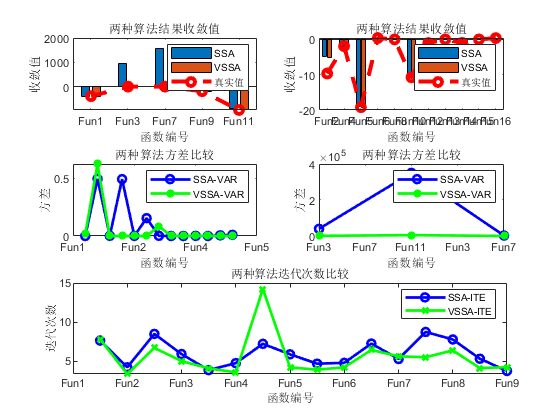

clear, close all
% data = load('C.txt');
data = load('DD.txt');
% data = data(13:end, :)
% theta = 0:0.5*pi:2*pi;
% rho = 10 * ones(1, length(theta));
% figure
% polarplot(theta, rho,'--o')

fssa = data(:, 1);
fvssa = data(:, 2);
real = data(:, 3);
varssa = data(:, 4);
varvssa = data(:, 5);
itessa = data(:, 6);
itevssa = data(:, 7);

bigdata = [1, 3, 7, 9, 11];
smadata = [2, 4, 5, 6, 8, 10, 12, 13, 14, 15, 16];
% -------------------------------------------------------------------
b_fssa = fssa(bigdata);
b_fvssa = fvssa(bigdata);
b_real = real(bigdata);
b_varssa = varssa(bigdata);
b_varvssa = varvssa(bigdata);
b_itessa = itessa(bigdata);
b_itevssa = itevssa(bigdata);
% -------------------------------------------------------------------
s_fssa = fssa(smadata);
s_fvssa = fvssa(smadata);
s_real = real(smadata);
s_varssa = varssa(smadata);
s_varvssa = varvssa(smadata);
s_itessa = itessa(smadata);
s_itevssa = itevssa(smadata);
% ----------------------------------------------------------------
figure
subplot 321
bar([b_fssa, b_fvssa])
hold on
plot(1:length(b_real), b_real, 'gs--',"LineWidth", 3, "Marker", "o", "Color", 'r')
title('两种算法结果收敛值')
xlabel('函数编号')
ylabel('收敛值')
tick1 = cell(1, 5);
legend('SSA', 'VSSA', '真实值')
for i = 1:5
    tick1{i} = ['Fun', num2str(bigdata(i))];
end
% settick('re_shu',tick);
% 设置横坐标
set(gca,'XTickLabel', tick1);

% legend('SSA', 'VSSA', '真实值', 'SSA算法值', 'VSSA算法值')
% ----------------------------------------------------------------
subplot 322
bar([s_fssa, s_fvssa])
hold on
plot(1:length(s_real), s_real, 'gs--', "LineWidth", 3, "Marker", "o", "Color", 'r')
tick2 = cell(1, 11);
title('两种算法结果收敛值')
xlabel('函数编号')
ylabel('收敛值')
for i = 1:11
    tick2{i} = ['Fun', num2str(smadata(i))];
end
% settick('re_shu',tick);
% 设置横坐标
set(gca,'XTickLabel', tick2);

legend('SSA', 'VSSA', '真实值')
% ----------------------------------------------------------------

bg = [3, 7, 11];
sm = [1, 2, 4, 5, 6, 8, 9, 10, 12, 13, 14, 15, 16];
bv_ssa = varssa(bg);
sm_ssa = varssa(sm);
bv_vssa = varvssa(bg);
sm_vssa = varvssa(sm);
subplot 323
tick3 = cell(1, 13);
plot(1:13, sm_ssa, 'b-o', 1:13, sm_vssa, 'g-*', "LineWidth", 2)
legend('SSA-VAR', 'VSSA-VAR')
title('两种算法方差比较')
xlabel('函数编号')
ylabel('方差')
for i = 1:13
    tick3{i} = ['Fun', num2str(sm(i))];
end
% settick('re_shu',tick);
% 设置横坐标
set(gca, 'XTickLabel', tick3);
% ----------------------------------------------------------------

subplot 324
tick4 = cell(1, 3);
plot(1:3, bv_ssa, 'b-o', 1:3, bv_vssa, 'g-*', "LineWidth", 2)
legend('SSA-VAR', 'VSSA-VAR')
title('两种算法方差比较')
xlabel('函数编号')
ylabel('方差')
for i = 1:3
    tick4{i} = ['Fun', num2str(bg(i))];
end
% settick('re_shu',tick);
% 设置横坐标
set(gca,'XTickLabel', tick4);
% plot(1:11, s_varvssa, 'b-o', 1:11, s_varssa, 'g-*')
% ----------------------------------------------------------------
subplot 313
tick5 = cell(1, 16);
plot(1:16, itessa, 'b-o', 1:16, itevssa, 'g-x', "LineWidth", 2)
for i = 1:16
    tick5{i} = ['Fun', num2str(i)];
end
title('两种算法迭代次数比较')
xlabel('函数编号')
ylabel('迭代次数')
legend('SSA-ITE', 'VSSA-ITE')
% settick('re_shu',tick);
% 设置横坐标
set(gca,'XTickLabel', tick5);


% figure
% for i = 1:16
%     rho1 = [fssa(i), real(i), varssa(i), itessa(i), fssa(i)];
%     rho2 = [fvssa(i), real(i), varvssa(i), itevssa(i), fvssa(i)];
% %     subplot(4, 4, i)
%     figure
%     polarplot(theta, rho1,'--o')
%     hold on
%     polarplot(theta, rho2,'--o')
%     rlim([min(min(rho2), min(rho1)), max(max(rho1), max(rho2))])
% %     break
% end












